# 快速傅里叶变换计算

% 计算时间序列的DFT绝对值

% 按时间窗归一化的傅里叶谱振幅绝对值

% 傅里叶振幅谱密度绝对值

% 傅里叶谱的真振幅

clearvars
%--使用持续的周期信号x(t)=3*sin(2*pi*t)+1.5*sin(2*pi*5*t)+2--------------------
inv         = 0.02;                             %采样频率
shoLen      = 1000;                             %短数据长度
shoSeq      = inv*(1:shoLen);
shoDat      = 4*sin(2*pi*shoSeq)+2*sin(2*pi*5*shoSeq)+2;   %???为什么不使用3*sin(2*pi*t)+1.5*sin(2*pi*5*t)+2???
lonLen      = 4000;                             %长数据长度
lonSeq      = inv*(1:lonLen);
lonDat      = 4*sin(2*pi*lonSeq)+2*sin(2*pi*5*lonSeq)+2;

绘制生成波形

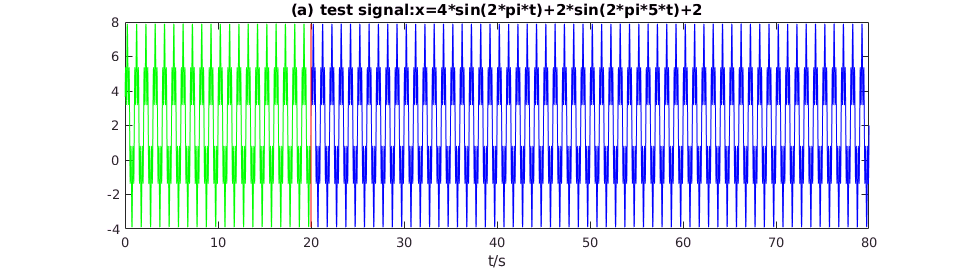

scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/3 scrsz(4)/2 scrsz(3)/2 scrsz(4)/4])
%???按书中说前1000个点，后面4000个点，（1000+4000）× 0.02=100s，不应该是80s的时间长,第二章P20???

%长80s绘图
plot(lonSeq(1:lonLen),lonDat(1:lonLen),'b')
hold on
plot(shoSeq(1:shoLen),shoDat(1:shoLen),'g')
hold on
plot([inv*shoLen,inv*shoLen],[max([shoDat,lonDat]),min([shoDat,lonDat])],'r')
xlabel('t/s')
title('(a) test signal:x=4*sin(2*pi*t)+2*sin(2*pi*5*t)+2')

## 计算特征值

shoDf=1/(shoLen*inv);                   %???为什么横坐标这么计算???
shoF=shoDf*(1:shoLen)-shoDf;
lonDf=1/(lonLen*inv);
lonF=lonDf*(1:lonLen)-lonDf;

计算变换系数绝对值

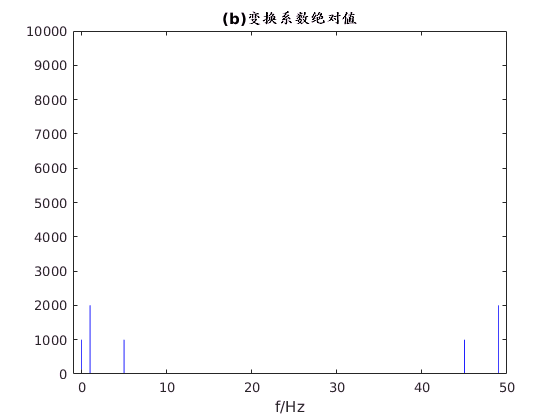

shoFft=fft(shoDat);
shoDftAbs=abs(shoFft);
shoDftAbs(1)=shoDftAbs(1)/2;            %???为什么第一个值要取一半值???
lonFft=fft(lonDat);
lonDftAbs=abs(lonFft);
lonDftAbs(1)=lonDftAbs(1)/2;

figure;
bar(shoF(1:shoLen),shoDftAbs(1:shoLen),2,'b')
axis([-1 shoDf*shoLen 0 10000])
title('(b)变换系数绝对值')
xlabel('f/Hz')

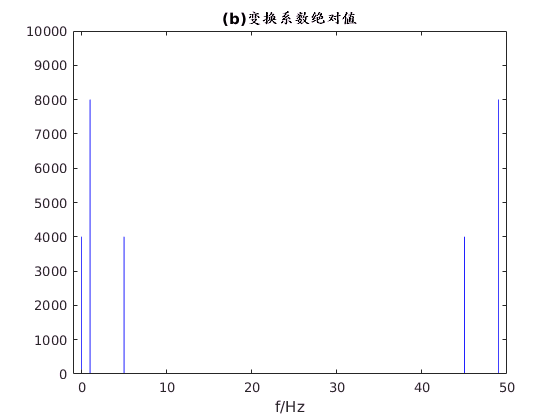

figure;
bar(lonF(1:lonLen),lonDftAbs(1:lonLen),8,'b')
axis([-1 lonDf*lonLen 0 10000])
title('(b)变换系数绝对值')
xlabel('f/Hz')

计算谱振幅绝对值

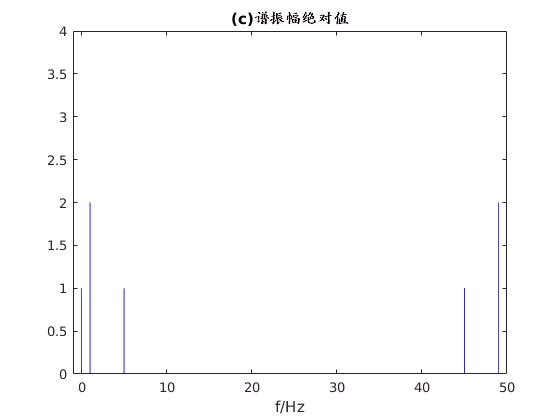

shoFnAbs=abs(shoFft/shoLen);
shoFnAbs(1)=shoFnAbs(1)/2;              
lonFnAbs=abs(lonFft/lonLen);
lonFnAbs(1)=shoFnAbs(1)/2;

figure;
bar(shoF(1:shoLen),shoFnAbs(1:shoLen),2,'b')
axis([-1 shoDf*shoLen 0 4])
title('(c)谱振幅绝对值')
xlabel('f/Hz')

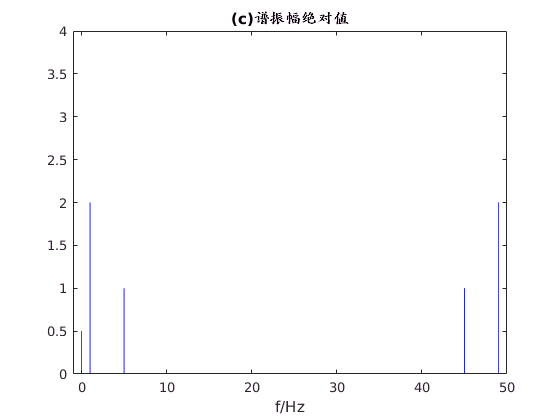

figure;
bar(lonF(1:lonLen),lonFnAbs(1:lonLen),8,'b')
axis([-1 lonDf*lonLen 0 4])
title('(c)谱振幅绝对值')
xlabel('f/Hz')

计算振幅谱密度绝对值

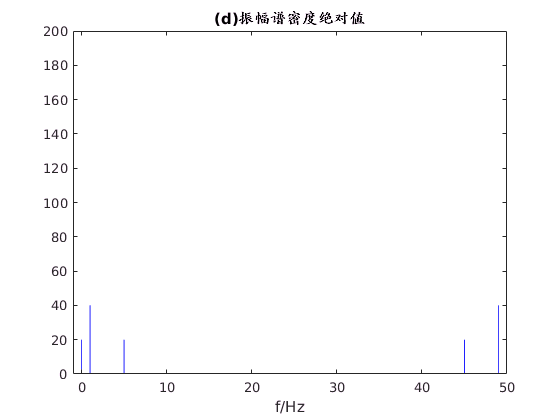

shofndAbs=abs(inv*shoFft);
shofndAbs(1)=shofndAbs(1)/2;
lonFndAbs=abs(inv*lonFft);
lonFndAbs(1)=lonFndAbs(1)/2;

figure;
bar(shoF(1:shoLen),shofndAbs(1:shoLen),2,'b')
axis([-1 shoDf*shoLen 0 200])
title('(d)振幅谱密度绝对值')
xlabel('f/Hz')

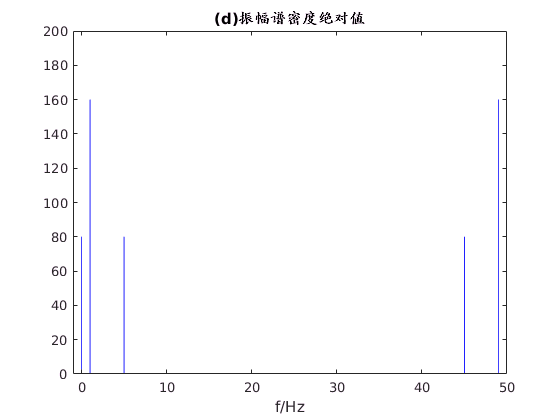

figure;
bar(lonF(1:lonLen),lonFndAbs(1:lonLen),8,'b')
axis([-1 lonDf*lonLen 0 200])
title('(d)振幅谱密度绝对值')
xlabel('f/Hz')

计算谱真实振幅

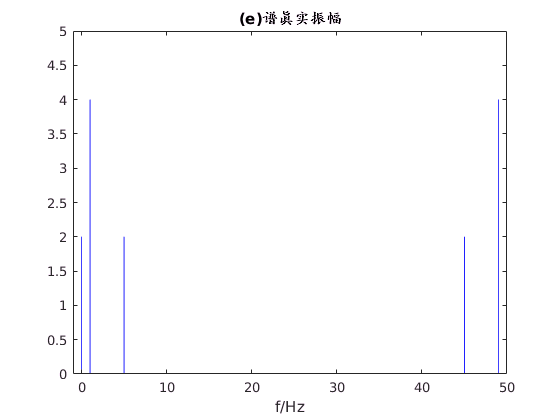

shoReaAmp=2*abs(shoFft)/shoLen;
shoReaAmp(1)=shoReaAmp(1)/2;
lonReaAmp=2*abs(lonFft)/lonLen;
lonReaAmp(1)=lonReaAmp(1)/2;

figure;
bar(shoF(1:shoLen),shoReaAmp(1:shoLen),2,'b')
axis([-1 shoDf*shoLen 0 5])
title('(e)谱真实振幅')
xlabel('f/Hz')

figure;
bar(lonF(1:lonLen),lonReaAmp(1:lonLen),8,'b')
axis([-1 lonDf*lonLen 0 5])
title('(e)谱真实振幅')
xlabel('f/Hz')

使用地震记录波形

load('M02_04_dalianE1.txt');                       %读入一道波形数据
lonLen      = 16000;
shoLen      = 8000;
lonDat      =M02_04_dalianE1(2501:lonLen+2500);
shoDat      =M02_04_dalianE1(2501:shoLen+2500);
inv         = 0.02;                                %采样频率
shoSeq      = inv*(1:shoLen);
lonSeq      = inv*(1:lonLen);

绘制生成波形

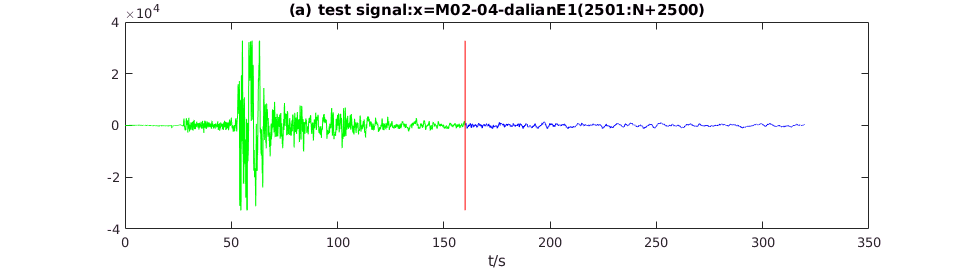

scrsz = get(groot,'ScreenSize');
figure('Position',[scrsz(3)/3 scrsz(4)/2 scrsz(3)/2 scrsz(4)/4])
plot(lonSeq(1:lonLen),lonDat(1:lonLen),'b')
hold on
plot(shoSeq(1:shoLen),shoDat(1:shoLen),'g')
hold on
plot([inv*shoLen,inv*shoLen],[max(lonDat),min(lonDat)],'r')
xlabel('t/s')
title('(a) test signal:x=M02-04-dalianE1(2501:N+2500)')

## 计算特征值

shoDf=1/(shoLen*inv);
shoF=shoDf*(1:shoLen)-shoDf;
lonDf=1/(lonLen*inv);
lonF=lonDf*(1:lonLen)-lonDf;

计算变换系数绝对值

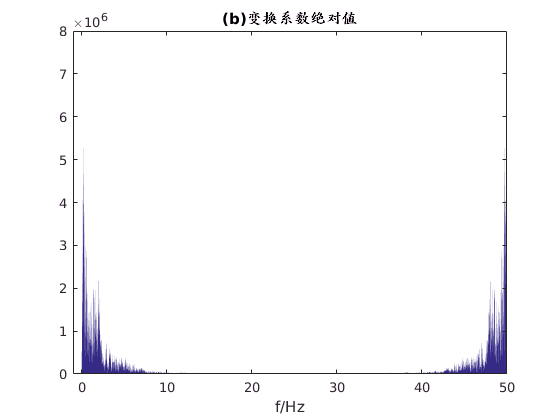

shoFft=fft(shoDat);
shoDftAbs=abs(shoFft);
shoDftAbs(1)=shoDftAbs(1)/2;
lonFft=fft(lonDat);
lonDftAbs=abs(lonFft);
lonDftAbs(1)=lonDftAbs(1)/2;
figure;
bar(shoF(1:shoLen),shoDftAbs(1:shoLen),2)
axis([-1 shoDf*shoLen 0 8000000])
title('(b)变换系数绝对值')
xlabel('f/Hz')

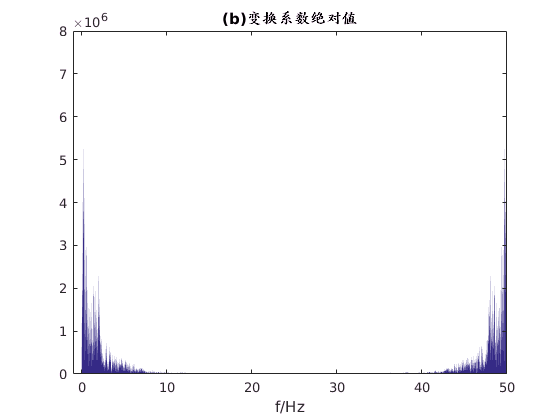

figure;
bar(lonF(1:lonLen),lonDftAbs(1:lonLen),2)
axis([-1 lonDf*lonLen 0 8000000])
title('(b)变换系数绝对值')
xlabel('f/Hz')

计算谱振幅绝对值

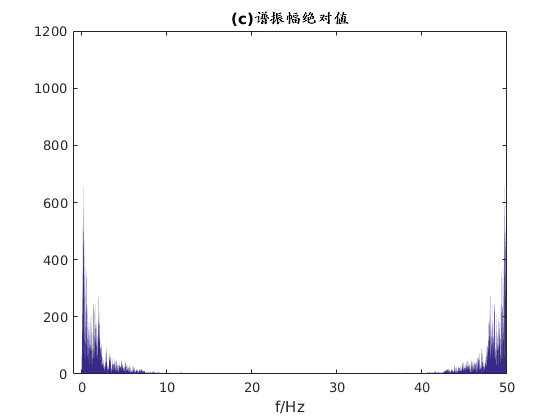

shoFnAbs=abs(shoFft/shoLen);
shoFnAbs(1)=shoFnAbs(1)/2;
lonFnAbs=abs(lonFft/lonLen);
lonFnAbs(1)=lonFnAbs(1)/2;
figure;
bar(shoF(1:shoLen),shoFnAbs(1:shoLen),2)
axis([-1 shoDf*shoLen 0 1200])
title('(c)谱振幅绝对值')
xlabel('f/Hz')

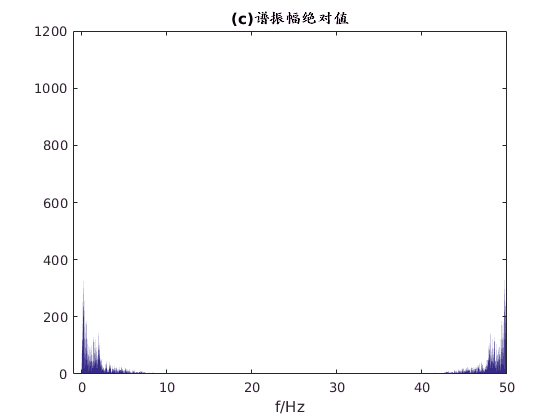

figure;
bar(lonF(1:lonLen),lonFnAbs(1:lonLen),2)
axis([-1 lonDf*lonLen 0 1200])
title('(c)谱振幅绝对值')
xlabel('f/Hz')

## 计算振幅谱密度绝对值

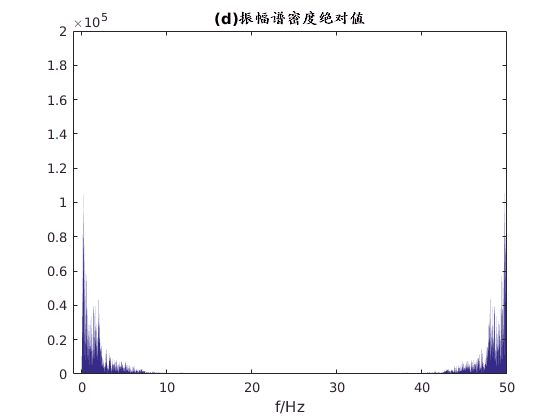

shofndAbs=abs(inv*shoFft);
shofndAbs(1)=shofndAbs(1)/2;
lonFndAbs=abs(inv*lonFft);
lonFndAbs(1)=lonFndAbs(1)/2;
figure;
bar(shoF(1:shoLen),shofndAbs(1:shoLen),2)
axis([-1 shoDf*shoLen 0 200000])
title('(d)振幅谱密度绝对值')
xlabel('f/Hz')

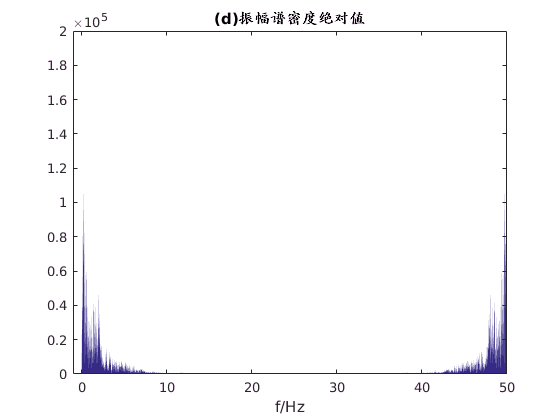

figure;
bar(lonF(1:lonLen),lonFndAbs(1:lonLen),2)
axis([-1 lonDf*lonLen 0 200000])
title('(d)振幅谱密度绝对值')
xlabel('f/Hz')

计算谱真实振幅

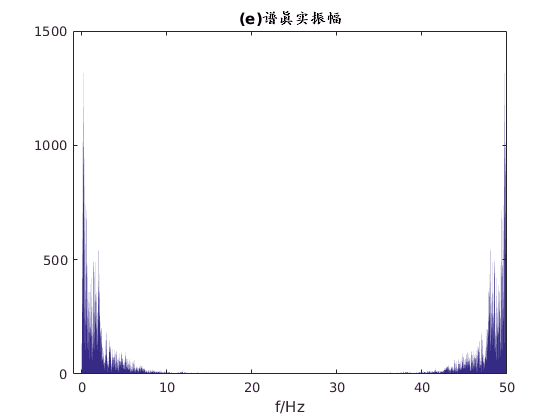

shoReaAmp=2*abs(shoFft)/shoLen;
shoReaAmp(1)=shoReaAmp(1)/2;
lonReaAmp=2*abs(lonFft)/lonLen;
lonReaAmp(1)=lonReaAmp(1)/2;

figure;
bar(shoF(1:shoLen),shoReaAmp(1:shoLen),2)
axis([-1 shoDf*shoLen 0 1500])
title('(e)谱真实振幅')
xlabel('f/Hz')

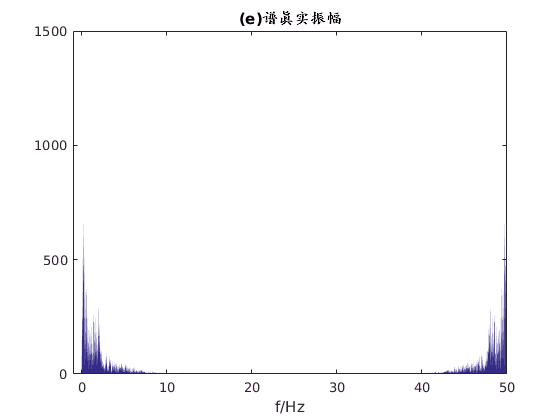

figure;
bar(lonF(1:lonLen),lonReaAmp(1:lonLen),2)
axis([-1 lonDf*lonLen 0 1500])
title('(e)谱真实振幅')
xlabel('f/Hz')